close all; clear all; clc;

N=256; % signal length
M=75; % select the number of DCT coefficients

% Load the test signal
load mit200
x=ecgsig(1:N,1);

% DCT transform of signal (FROM MOTE)
y =[-57.0  30.0  -22.0  9.0  -2.0  10.0  11.0  -6.0  16.0  -10.0  19.0  -7.0  14.0  -2.0  4.0  6.0  -3.0  10.0  -5.0  7.0  0.0  0.0  6.0  -6.0  8.0  -6.0  4.0  0.0  0.0  3.0  -3.0  3.0  -3.0  0.0  -1.0  -2.0  0.0  -3.0  0.0  -2.0  0.0  -1.0  -1.0  -1.0  -1.0  -1.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  1.0  0.0  1.0  0.0  0.0  1.0  0.0  1.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0];

% apply scaling
y(1)=1/sqrt(N)*y(1);
y(2:end)=sqrt(2/N)*y(2:end);

%% Select first M coefficients
y(M+1:end)=0;

%% reconstructed signal
x_rec=idct(y);

% Mean square
mse(x,x_rec);

plot(x);
hold on;
plot((x_rec), 'r.');
fprintf('Mean square: %f\n', mse(x,x_rec))

Mean square: 0.155425


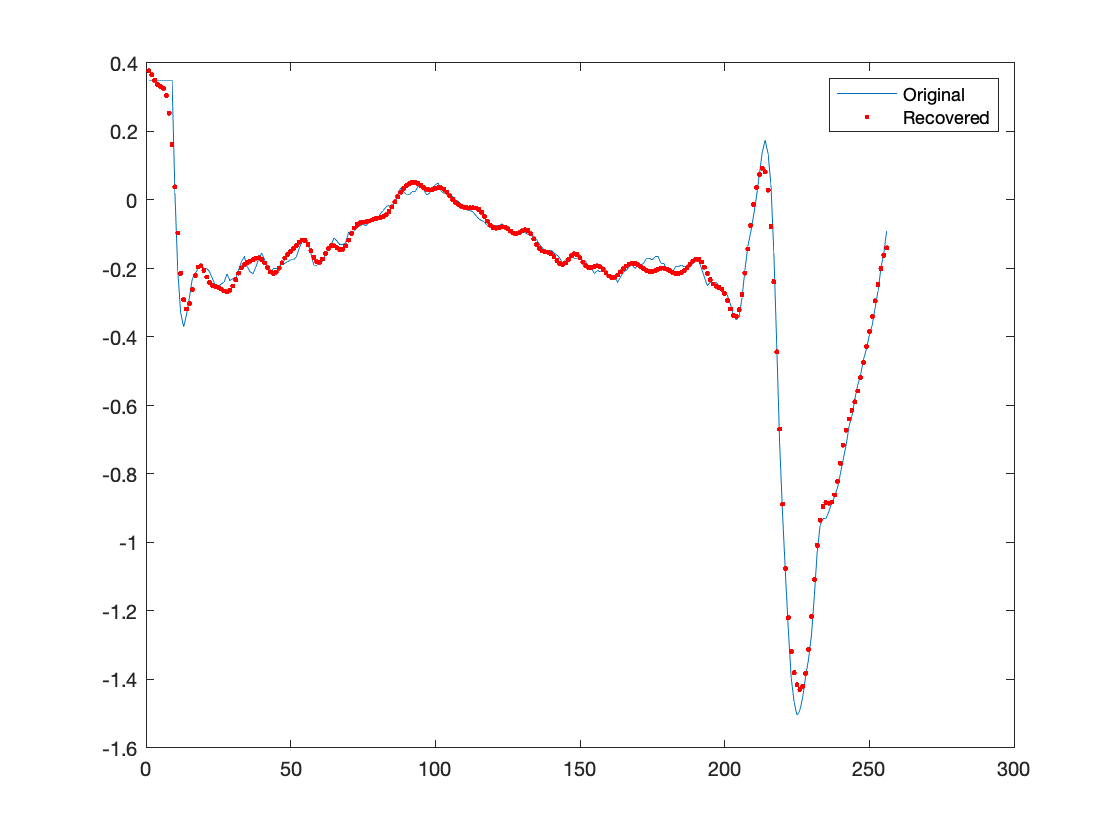

legend('Original', 'Recovered')